# **Find All Peaks Example**

## Code

### Create Function

x_length = 1000;
x = linspace(0,1,x_length);
PeakSig = peakSigFcn(x, x_length);

### Initialize findAllPeaks options

options = struct;
options.includeInitialPeak = true;
options.includeFinalPeak = true;

### Run findAllPeaks function

[positive, negative, all] = findAllPeaks(PeakSig,x,options);

## Plot results


figure
yyaxis 'left'

### Plot function

plot(x, PeakSig);
hold on

### Add positive peaks in red

plot([positive.location],[positive.peak],'v','MarkerSize',5,...
    'MarkerEdgeColor','black',...
    'LineStyle','none',...
    'MarkerFaceColor','red')


### Add negative peaks in green

plot([negative.location],[negative.peak],'^','MarkerSize',5,...
    'MarkerEdgeColor','black',...
    'LineStyle','none',...
    'MarkerFaceColor','green')


### Add base of peaks as cross markers

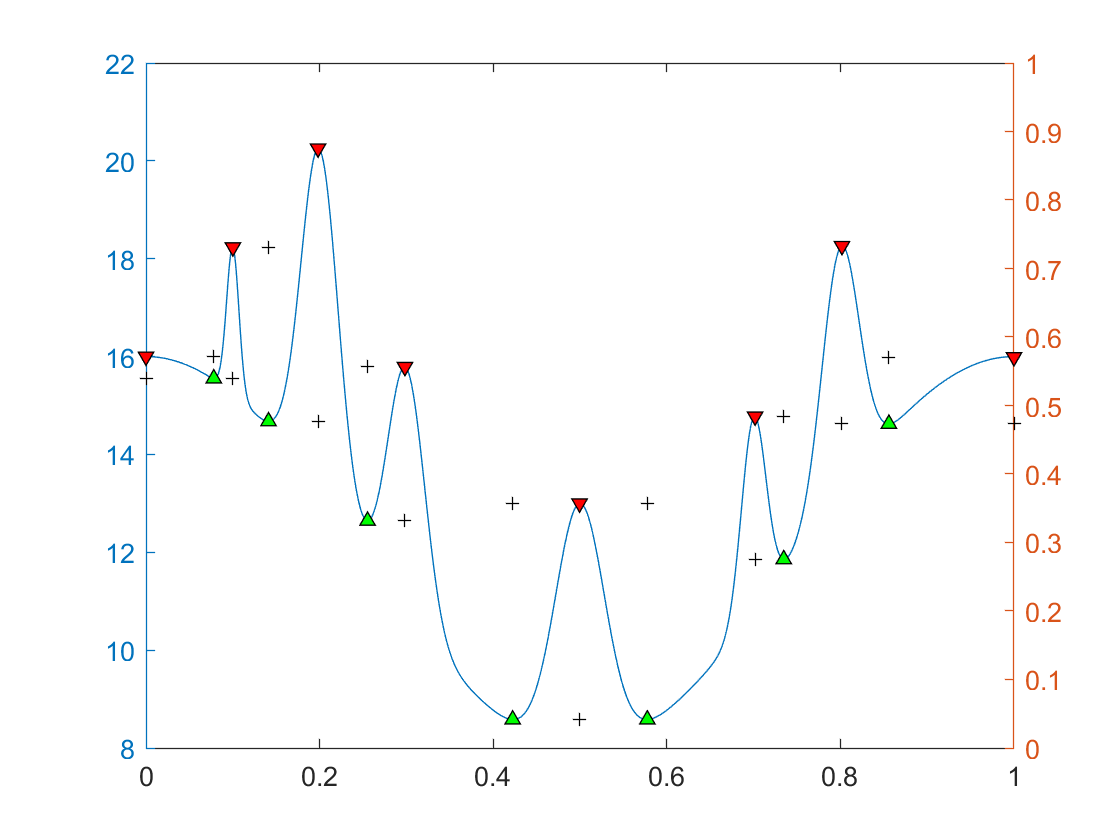

plot([all.location],[all.base],'+','MarkerSize',5,...
    'MarkerEdgeColor','black',...
    'LineStyle','none')